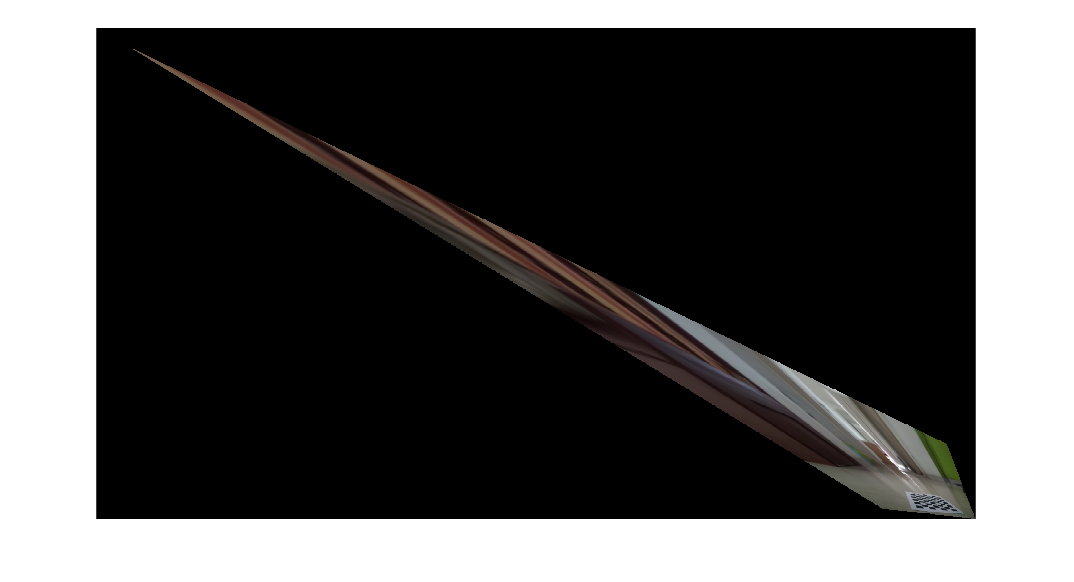

img = imread('peppers.png');
% Set angles here. Start with two of them set to zero and third set quite
% small to see the effect.
yaw = 0;  
pitch = -0.4; 
roll = 0.9;
% Set camera position here. To understand the effect of angles, move it
% along the z-axis and y-axis so it is above the centre of the top edge of
% the picture. Note that as cammoves is true in call to homography_matrix,
% the z-axis movement needs to be negative.
% The camera is looking along the z-axis.
campos = [size(img,2)/2; 0; -200];
% Construct a rotation matrix. My sign convention is opposite to
% angle2dcm, but I don't have the aerospace toolbox. Computed rmat agrees
% with example in angle2dcm documentation.
yawmat = rotation_matrix([0 0 1], -yaw);       % about z
pitchmat = rotation_matrix([0 1 0], -pitch);   % about y
rollmat = rotation_matrix([1 0 0], -roll);     % about x
rmat = rollmat * pitchmat * yawmat;   % zyx order - default for angle2dcm
% construct homography matrix
F = 100;    % focal length
hmat = homography_matrix([], rmat, campos, F, true);
% construct projective2d object
tform = projective2d(hmat.');
Ix = imread('k1.png');  % read the image into the matrix
imw_crop = imwarp(Ix, tform);
imshow(imw_crop);

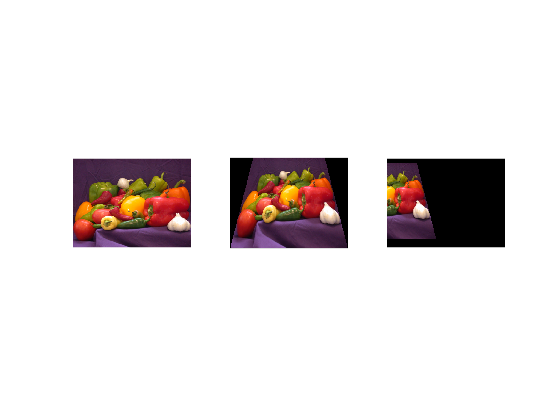

% display original image and results
subplot(1,3,1);
imshow(img);
% show image warped and cropped
imw_crop = imwarp(img, tform);
subplot(1,3,2);
imshow(imw_crop);
% show image warped in same coordinate system as original
imw_same = imwarp_same(img, tform);
subplot(1,3,3);
imshow(imw_same); shg;